%{
ES115 Engineering Computer Applications
Model Selection Challenge

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project compares different mathematical models to represent delivery
cost as a function of distance. Three models are used: a linear model,
a quadratic model, and a piecewise linear model. The goal is to analyze
how each model behaves, visualize their differences, and determine which
model best represents realistic delivery pricing over short and long
distances.

Inputs (Knowns):
- Distance values (x) from 0 to 50 miles
- Model A (Linear): A(x) = 2x + 10
- Model B (Quadratic): B(x) = 0.05x^2 + 1.5x + 8
- Model C (Piecewise):
    • For x ≤ 20: C(x) = 1.8x + 12
    • For x > 20: C(x) = 2.5x − 10

Outputs (Unknowns):
- Cost values for each model
- Graph comparing all three models
- Visual understanding of how cost changes with distance
- Insight into which model best fits different scenarios

Engineering Workflow and Algorithms:
- Define distance values over the given range
- Create equations for each model (linear, quadratic, piecewise)
- Apply piecewise conditions for Model C
- Evaluate cost values for all models
- Plot all models on the same graph for comparison
- Analyze differences in growth behavior and trends

MATLAB Tools / Functions Used:
- plot() for graphing multiple models
- logical indexing for piecewise conditions
- element-wise operations (.^) for quadratic calculations
- hold on for overlaying plots
- legend(), title(), xlabel(), ylabel() for labeling

Reflection After Completing the Project:
- I learned how different types of models can represent the same real-world
  situation in different ways and how their behavior changes over a range.
- I also understood that linear models are simple, quadratic models show
  increasing rates, and piecewise models can represent real pricing changes.
- If I were to improve this, I would compare the models using actual data
  to determine which one is most accurate.
- Difficulty Rating: 5/10 — creating the models was straightforward, but
  comparing and interpreting them required more thinking.
%}



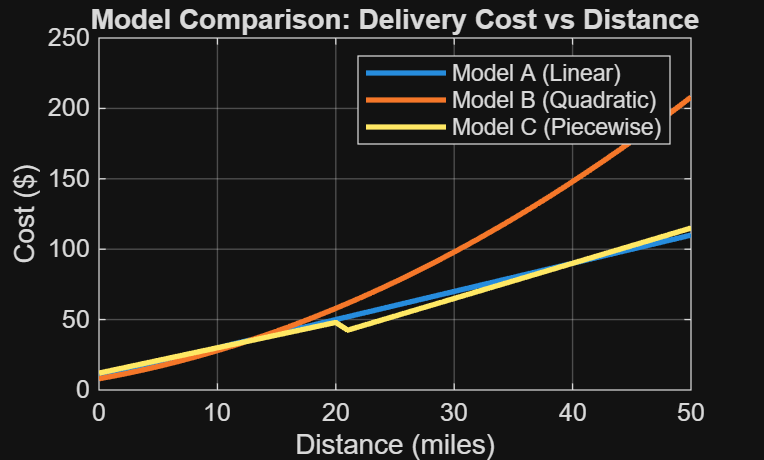

 
clear; clc; close all; 
 
% ---------------------------- 
% Scenario: Delivery Cost vs Distance 
 
x = 0:1:50; % distance (miles) 
 
% ---------------------------- 
% Model A: Linear 
% Constant rate + base fee 
A = 2*x + 10; 
 
% ---------------------------- 
% Model B: Quadratic 
% Cost increases faster at longer distances 
B = 0.05*x.^2 + 1.5*x + 8; 
 
% ---------------------------- 
% Model C: Piecewise Linear 
C = zeros(size(x)); 
 
% Short distances 
C(x <= 20) = 1.8*x(x <= 20) + 12; 
 
% Long distances 
C(x > 20) = 2.5*x(x > 20) - 10; 
 
% ---------------------------- 
% Plot all models 
figure; 
plot(x, A, 'LineWidth', 2); hold on; 
plot(x, B, 'LineWidth', 2); 
plot(x, C, 'LineWidth', 2); 
 
title('Model Comparison: Delivery Cost vs Distance'); 
xlabel('Distance (miles)'); 
ylabel('Cost ($)'); 
legend('Model A (Linear)', 'Model B (Quadratic)', 'Model C (Piecewise)'); 
grid on; 